# Error Types, P-Values, False-Positives, and Power Analysis

## Exercise 1

Do a post-hoc power analysis to determine the number of data samples needed to achieve 80% power for a series of possible effect sizes. Notes and tips:

- Given that the data have already been collected, note that this is technically a "post-hoc" power analysis and is for demonstration purposes only. Normally these analyses must be done **before** collecting data.

- Assume that a "data sample" is simply the non-parametric correlation coefficient between pupil diameter and LC activty measured in a given session.

- Thus, to obtain a null distribution of these data samples, compute the correlation coefficients on simulated data that are independently generated from Poisson (for LC spiking data) and Gaussian (for pupil data)distributions.

- Then plot n (number of data samples, corresponding to correlation coefficients measured in a single expermental session) needed for 80% power as a function of effect sizes.

- To compute power, you can use TTestIndPower in Python, or sampsizepwr in Matlab'

ToDo 

- Generate data from Poisson and from Gaussian distribution 

- Compute Correlation Coefficient

- Plot n (data number based on corelation coeffieicent) as fxn of effect size needed for 80% power

- Use the samplesizepwer function

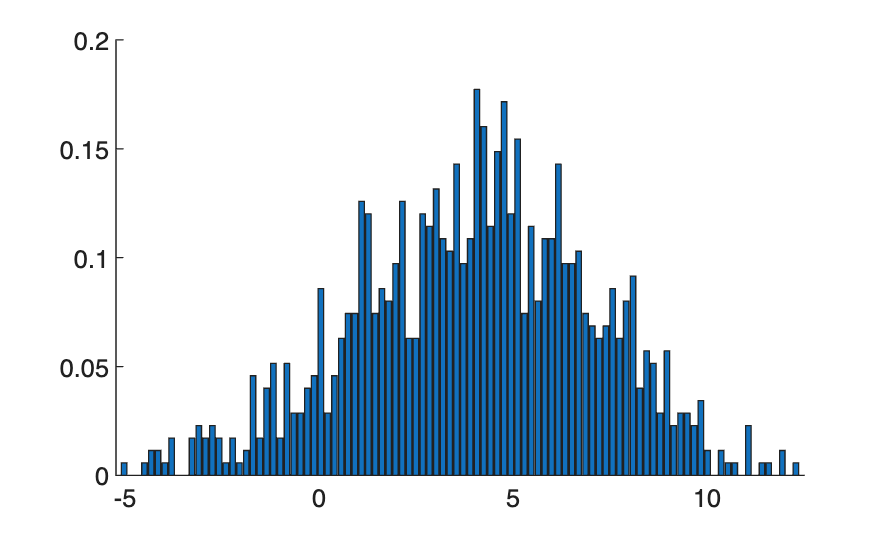

% Generate Gaussian Data
mu = 4;
sigma = 3;
N = 1000;

% Get samples
samples = normrnd(mu, sigma, N, 1);

% plot histogram, pick number of bins
cla reset; hold on;
nbins = 100;
[counts, edges] = histcounts(samples, nbins);
xaxis = edges(1:end-1)+diff(edges);
npdf = counts./trapz(xaxis, counts);
bar(xaxis, npdf);


% Completed with help from: https://praneethnamburi.com/2015/02/05/simulating-neural-spike-trains/
fr = 100; 
dt = 1/1000; 
nBins = 10; 
poissonSpikeTrain = rand(N, nBins) < fr*dt; 
0:dt:1-dt;

% Calculate the correlation Coefficient using the two distributions
% nullDist = Corr(X, Y); 

% Set up some more variables
nn = 1:100;
mu2 = 100; 
sd = 5; 
null = 102; 
pwr = 0.8; 

% Determine the sample size for selected power and generate power curve 
nout = sampsizepwr('t',[mu2 sd], null, pwr)

nout = 52

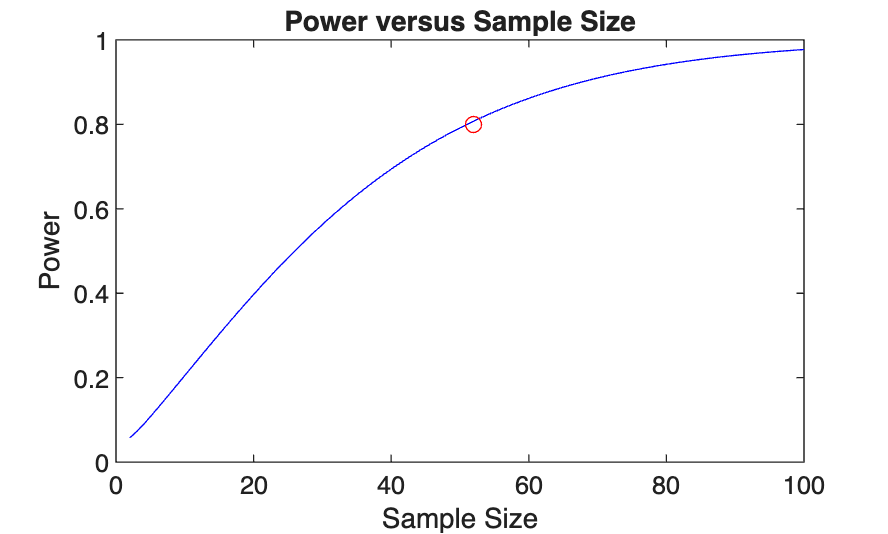

pwrout = sampsizepwr('t',[mu2 sd], null, [], nn);

% Plot results as a function of sample size
figure;
plot(nn,pwrout,'b-',nout,0.8,'ro')
title('Power versus Sample Size')
xlabel('Sample Size')
ylabel('Power')